thermalmodel = createpde('thermal', 'steadystate');
epsilon = 0.1

epsilon = 0.1000

gm = multicuboid([2 5],[2 + epsilon, 5 + epsilon],5, "Void", [true, false])

gm =   DiscreteGeometry with properties:

       NumCells: 1
       NumFaces: 10
       NumEdges: 24
    NumVertices: 16
       Vertices: [16×3 double]

thermalmodel.Geometry = gm

thermalmodel =   ThermalModel with properties:

               AnalysisType: "steadystate"
                   Geometry: [1×1 DiscreteGeometry]
         MaterialProperties: []
                HeatSources: []
    StefanBoltzmannConstant: []
         BoundaryConditions: []
          InitialConditions: []
                       Mesh: []
              SolverOptions: [1×1 pde.PDESolverOptions]

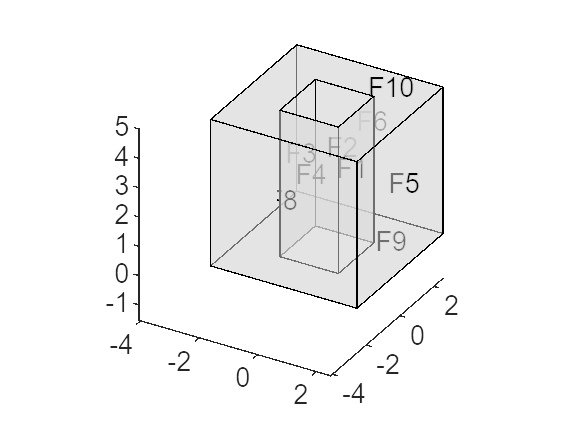

pdegplot(thermalmodel,"FaceLabels","on","FaceAlpha",0.5)

generateMesh(thermalmodel)

ans =   FEMesh with properties:

             Nodes: [3×29354 double]
          Elements: [10×19407 double]
    MaxElementSize: 0.3487
    MinElementSize: 0.1744
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'

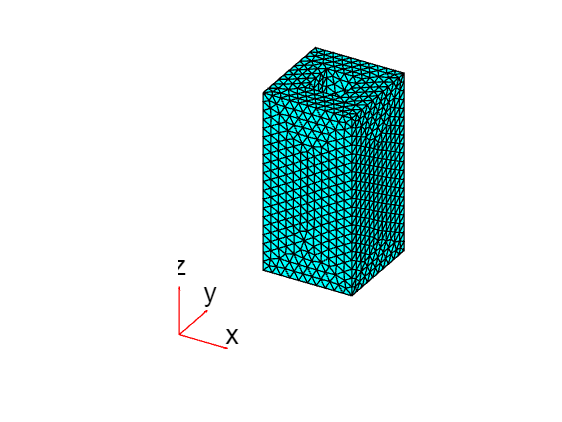

pdemesh(thermalmodel)

xLength = max(thermalmodel.Mesh.Nodes(1,:)) - min(thermalmodel.Mesh.Nodes(1, :))

xLength = 5.0000

yLength = max(thermalmodel.Mesh.Nodes(2,:)) - min(thermalmodel.Mesh.Nodes(2, :))

yLength = 5.1000

zLength = max(thermalmodel.Mesh.Nodes(3,:)) - min(thermalmodel.Mesh.Nodes(3, :))

zLength = 5.0000

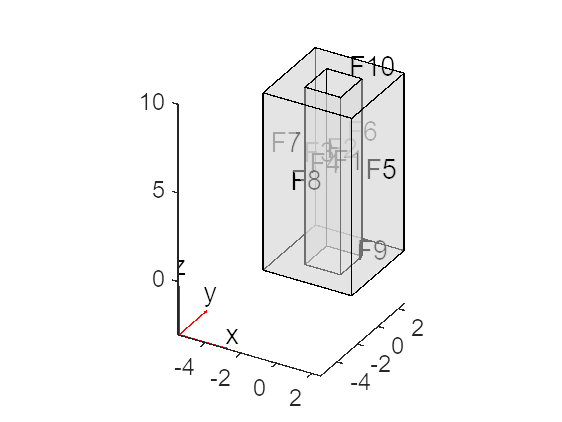

thermalProperties(thermalmodel, 'Cell', 1, 'ThermalConductivity', 25);
thermalBC(thermalmodel, 'Face', 1:thermalmodel.Geometry.NumFaces, ...
    'ConvectionCoefficient', 25, 'AmbientTemperature', 288.15);
pdegplot(thermalmodel, 'FaceLabels','on', 'FaceAlpha',0.5)

thermalBC(thermalmodel, 'Face', 9, 'Temperature', 288.15);
thermalBC(thermalmodel, 'Face', 7, 'HeatFlux', 10);
thermalBC(thermalmodel, 'Face', 5, 'HeatFlux', -5);

Timing the analysis

tic 
results = solve(thermalmodel);
time = toc

time = 1.2855

Post-Processing

t_max = max(results.Temperature)

t_max = 288.9273

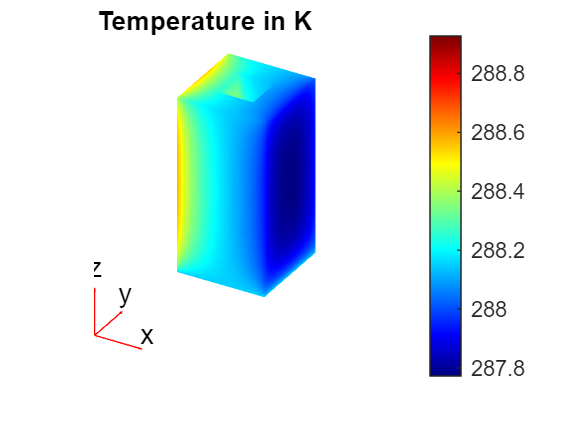

pdeplot3D(thermalmodel, 'ColorMapData',results.Temperature)
title('Temperature in K')
colorbar

Perform a parallel toolbox analysis

%thermalConductivities = [45 50 68 75 88];
%runtime = time * length(thermalConductivities)

Using parfor

%maxTemperatures = zeros(size(thermalConductivities));
%parfor i = 1:length(thermalConductivities)
%    thermalProperties(thermalmodel, 'Cell', 1, ...
%        'ThermalConductivity',thermalConductivities(i));
%    results = solve(thermalmodel);
%    maxTemperatures(i) = max(results.Temperature)
%end


%plot(thermalConductivities, maxTemperatures, 'o')
%xlabel('Thermal Conductivities $\frac{W}{mK}$', 'Interpreter', 'latex')
%ylabel('Max Temperature $^\circ$K', 'Interpreter','latex')
%title('Max Temperature v. Thermal Conductivity')


%linearmodel = fitlm(thermalConductivities(:), maxTemperatures(:), 'VarNames', ...
%    {'ThermalConductivity', 'MaxTemperature'})

%plot(linearmodel)
